# Решение  одномерной обратной задачи нестационарной теплопроводности методом конечных разностей

## Условие (математической) корректности задачи по Адамару 

- Решение существует

- Решение единственно

- Решение непрерывно зависит от входных параметров (устойчиво). То есть, небольшие изменения входных параметров не должны приводить к "большим" изменениям выходных.

#### Пример: корректности в задаче линейной регресии

Посмотрим эти критерии на примере простой обратной задачи - обращения линейного оператора:


$$A\vec{b}=\vec{y}$$


Если $A$ - сингулярна (ранг матрицы меньше размерности пространства ее столбцов или строк, то есть ее нуль-пространство является нетривиальным) или неквадратная, то данная задача является некорректной. Причем, в случае квадратной матрицы, если вектор $\vec{y}$ принадлежит нуль-пространству сингулярной матрицы $A$, то задача решения не имеет (то есть не корректна по первому критерию), а если $\vec{y}$ принадлежит пространству столбцов, то задача имеет бесконечно много решений, то есть  она не удовлетворяет второму критерию.

Если решать задачу линейной регрессии то :


$$argmin(||A\vec{b}-\vec{y}||_2^2)$$


Как известно, решение этой задачи дается псевдообратной матрицей $\vec{b}=A^{\dagger}\vec{y}$, однако псевдообратная матрица существует только для несингулярной матрицы $A$ (для квадратной несингулярной матрицы псевдообратная совпадает с обратной), в этом случае задача будет иметь единственное решение и будет корректной. Для сингулярной же матрицы предикторов ($A$) задача является некорректной по Адамару.

A = [1 2 3;1 2 -3;2 4 0] % матрица с двумя зависимыми столбцами

A =      1     2     3
     1     2    -3
     2     4     0


y = [3;3;3] 

y =      3
     3
     3


A\y

ans =       -Inf
       Inf
    0.5000


#### Регуляризация Тихонова*

Сделать задачу с сингулярной матрицей корректной может помочь регуляризация Тихонова (ridge regression), в простейшем виде:

$min(||A\vec{b}-\vec{y}||_2^2 + \alpha ||\vec{b}||_2^2)$ - формулировка исходной задачи в терминах наименьших квадратов. То есть регляризация помогает из бесконечого множества решений выбрать то, которое довлетворят дополнительному ограничению на множество параметров оптимизации (в данном случае это ограничение на длину вектора $\vec{b}$)

alfa = 0.1

alfa = 10

f = @(b)((A*b - y)'*(A*b - y) + alfa*b'*b)

f = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+alfa*b'*b)


fminsearch(f,rand(3,1)) % случайное положение 

ans =     0.3000
    0.6000
   -0.0000


% стартового вектора каждый раз приводит к разному ответу
% если alfa = 0  - регуляризация отсутсвует

Важный момент тут еще в том, что "верное" решение теперь зависит от параметра $\alpha$!

То есть, с точки зрения статистикого подхода, оценка становится смещенной! ( в отличие от оценки $A^{\dagger}\vec{y}$, которая, если существует является несмещенной.

clearvars
a = 0.1:0.1:30;
A = [1 2 ;1 2;2 4] % матрица с двумя зависимыми столбцами

A =      1     2
     1     2
     2     4


y = [3;3;3] 

y =      3
     3
     3


b_v = zeros(length(a),2);
counter=0

counter = 0

b_start = [2;1]

b_start =      2
     1


for ai = a
    f_i = @(b)((A*b - y)'*(A*b - y) + ai*b'*b);
    counter = counter + 1;
    b_v(counter,:) = fminsearch(f_i,b_start); % случайное положение 
end

f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


f_i = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+ai*b'*b)


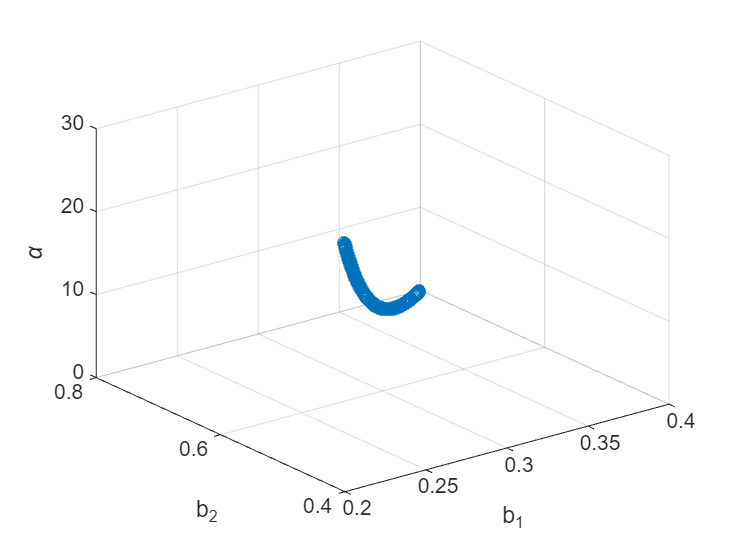

% зависимость решения от параметра регуляризации
scatter3(b_v(:,1),b_v(:,2),a)
zlabel("\alpha");ylabel("b_2");xlabel("b_1")

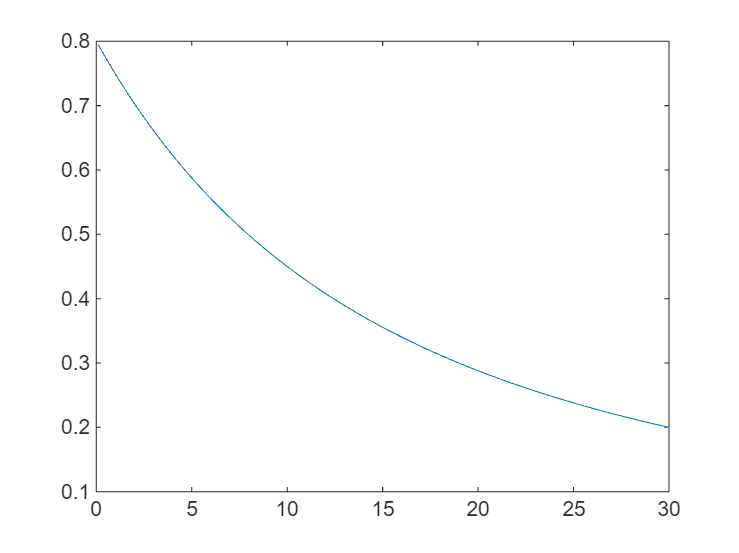

plot(a,sum(b_v'.*b_v'))

#### Принцип Морозова для выбора регуляризационного множителя 

Возникает вопрос как выбрать регуляризующий множитель?

Если речь идет о регуляризаци регрессионной задачи экспериментальных данных, которые были получены с некоторой погрешностью, можно, например, воспользоваться приципом Морозова, который гласит (в тривиальной интерпретации):

Параметр регуляризации $\alpha$ надо выбирать так, чтобы среднеквадратичная ошибка регрессии была равна дисперсии ошибки  $\vec{y}$ .

$A\vec{\beta} = \vec{y} + \vec{e}$, здесь $\vec{e}$ - случайный вектор ошибки.


$$N\sigma=\vec{e}^t\vec{e}$$


$||A\vec{b}_\lambda - \vec{y}||_2^2 =\tau\sigma N$, где

$\vec{b}_{\lambda} = argmin(||A\vec{b}-\vec{y}||_2^2 + \alpha ||\vec{b}||_2^2)$ - решение задачи регрессии

$\tau$ - некоторый множитель близкий к единице.

**Morozov's Discrepancy Principle**: This picks λλ such that the residual norm matches the expected noise level in the data, ensuring the fitted model does not overfit noise.

Если $A$ - несингулярна (ранг матрицы равен размерности пространства ее столбцов и строк, то есть, все ее столбцы / строки линейно независимы) то решение данной задачи существует и единственно, правда не всегда численно устойчиво.

$cond(A)= \frac {||A||}{||A^{-1}||}$ - число обсуловленности матрицы (conditional number)  - для l2 нормы это отношение максимального сингулярного значения к минимальному, чем оно больше, тем менее стабильным будет алгоритм обращения данной матрицы

$H_{ij} = \frac {1} {i+j-1}$ - матрица Гильберта пример матрицы у которой очень быстро растет .

sym(hilb(5))

$$ans = \left(\begin{array}{ccccc} 1 & \frac{1}{2} & \frac{1}{3} & \frac{1}{4} & \frac{1}{5}\\ \frac{1}{2} & \frac{1}{3} & \frac{1}{4} & \frac{1}{5} & \frac{1}{6}\\ \frac{1}{3} & \frac{1}{4} & \frac{1}{5} & \frac{1}{6} & \frac{1}{7}\\ \frac{1}{4} & \frac{1}{5} & \frac{1}{6} & \frac{1}{7} & \frac{1}{8}\\ \frac{1}{5} & \frac{1}{6} & \frac{1}{7} & \frac{1}{8} & \frac{1}{9} \end{array}\right)$$

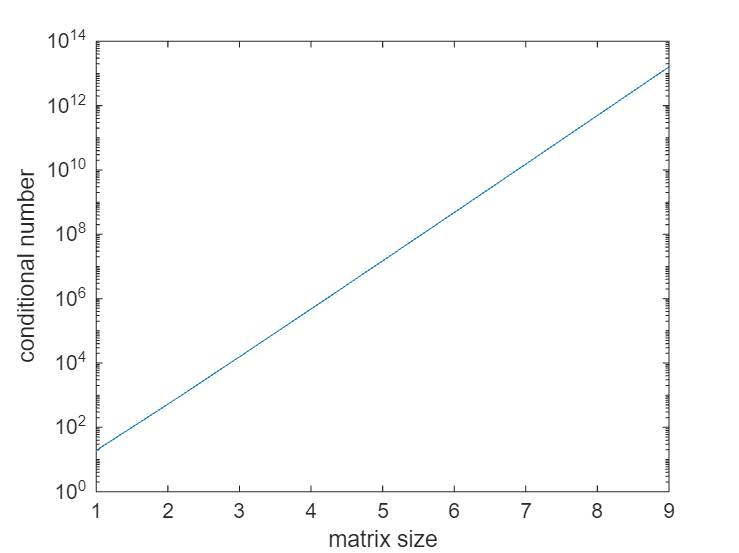


p = 2:10;
c_n = zeros(length(p),1);
for i = 1:length(p)
    p_i = p(i);
    c_n(i) = cond(hilb(p_i));% функция cond считает condition number
end
semilogy(c_n)
xlabel("matrix size");ylabel("conditional number")

Поэтому для достаточно больших размеров матрицы, решение будет неустойчиво, то есть небольшие изменения правой части будут приводить к значительным изменениям решения.

Тут опять может помочь регулялризация Тихонова.

A = hilb(8)

A =     1.0000    0.5000    0.3333    0.2500    0.2000    0.1667    0.1429    0.1250
    0.5000    0.3333    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111
    0.3333    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000
    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909
    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833
    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769
    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714
    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667


y = ones(8,1);
alfa = 0.1

alfa = 0.1000

f = @(b)((A*b - y)'*(A*b - y) + alfa*b'*b)

f = function_handle with value:
    @(b)((A*b-y)'*(A*b-y)+alfa*b'*b)


fminsearch(f,rand(8,1)) % случайное положение 

ans =    -0.3332
    0.8001
    1.0241
    1.0567
    1.0312
    0.9869
    0.9375
    0.8886


% стартового вектора каждый раз приводит к разному ответу
% если alfa = 0  - регуляризация отсутсвует

Хотя критерий неустойчивости Адамара это не тоже самое что численная неустойчивость, однко на практике математическая неустойчивость приводит к численной неустойчивости, что проявляется либо в зависимости от стартовых условий оптимизации, либо в расходимости процесса оптимизации.

## Некоторые общие сведения и терминология 

Если принять граничные условия, свойства материалов, внутренние источники тепла и геометрию объектов за **причину** теплобмена, а тепловое состояние  объекта за **следствие**, то  найти следствие по причине - это **прямая задача**, а причину по следувию - **обратная**.

Так как процесс теплоперенса протекает во времени, нельзя поставить эксперимент по измерению непосредственно **причины, **отсюда следует "физическая" некорректность постановки обратных задач.

Обратные задачи можно разделить на три класса:

- идентификации тепловых процессов

- проектирования

- управления процессами

Принципиальным отличием первой задачи от второй и третьей можно назвать то, что для последних, наличие множества "верных" решений (**некорректность**) это хорошо, так как годится любое решение, удовлетворяющее техническому результату  с заданной точностью. Пример - расчет многослойных структур для диэлектрики,  существует много различных структур удовлетворяющих заданной частотной зависимости. Тоже самое и с задачей управления, если решения ОЗ возвращает управляющйи сигнал, который дает нужный отклик, то нам этого достаточно. В случае идентификации множественность решений усложняет ситуацию, так, как истинная причина теплового состояния системы была одна. Например, может быть что измеренной в некоторых точках темперутре образца соотвествует множество кривых для температурной зависимости теплопроводности, тогда возникает вопрос как выбрать одну из множества (**регуляризация**).

Постановку задач можно разделить на два класса:

- с сосредоточенными (lumped) параметрами (задачи теплообмена)

- с распределенными (disctributed) параметрами (задачи теплопроводности)

Первый класс задач строится на представлении системы как совокупности отдельных объектов, которые взаимодействуют через интерфейсы, развитие этой системы во времени сводится к решению системы обыкновенных дифференциальных или дифференциально-алгебраических уравнений (matlab simulink, julia dyad). Причем, отдельные блоки внутри могут решать и уравнения в частных производных.

Например, если у нас есть $N$ изотермических элементов (то есть, каждый отдельный элемент характеризуется некоторой одной температурой), $r$ элементов при этом взаимодействуют в окружающей средой через конвекцию, а $s$  - через излучение, кроме того в каждом $n$-м элементе может выделяться тепло $Q_n$, тогда, согласно закону сохранения энергии, скорость изменения запасенного количества теплоты для каждого элемента определяется балансом поступающего к нему извне и отдаваемому им вовне тепла:

$C_n \frac {dT_n}{dt} = \Sigma_{j=1}^{N+r}\lambda_{jn}(T_j - T_n) + \Sigma_{j=1}^{N+s}K_{nj}\sigma(T_j^4 - T_n^4)A_n + Q_{n}$                                         (1)


$$n \in [1...N]$$


В уравнении выше, "причинами" являются взаимосвязи между элементами и температуры окружающего пространства, а "следствиями"  - зависимости температур элементов от времени.

$C_n$ - теплоемкость, $T_n$ - температуры элементов, $T_r$ - температуры "восстановления" окружающего пространтва, $\lambda_{jn}$ - коэффициенты теплоотдачи как взаимные между элементами, так и между элементами и окружающей средой (в общем случае каждый

элемент может быть окружен средой со своей темепратурой востановления и коэффициентом теплоотдачи), $K_{nj}$ -  коэффициенты облучения, зависящие в общем случае от угловых коэффициентов $F_{jn}$ (view factors) и излучательных способностей объектов $\epsilon_{n}$ и $\epsilon_{j}$, $A_n$ - площадь обекта, $Q_n$ - внутренние источники тепла.

Уравнение (1) может быть вкратце переписано как нелинейное обыкновенное дифференциальное уравнение:


$$\frac {d\vec{T}}{dt} = \Phi (\vec{T})$$


Здесь $\vec{T} = \matrix { T_i \cr \vdots \cr T_N}$, а $\Phi$ - некоторый нелинейный в общем случае оператор, который возвращает вектор равный по размеру вектору $\vec{T}$.

Второй класс обратных задач (задачи с распределенными параметрами) построен на решении дифференциальных уравнений в частных производных (ДУЧП), второй сводится к решению обыкновенных дифференциальных уравнений.  Задачи первого класса по отношению к тому, какую из составляющих ДУЧП надо восстановить

## Уравнение теплопроводности

изменение запасенной в объеме энергии = поток энергии, выходящий из объема вовне + произведенная внутренними источниками энергия


$$\frac{d}{dt} \int\int\int_V \rho c (T) \, dV = - \int\int_S \vec{q} \cdot \vec{n}  dS +\int\int\int_V  Q \, dV$$


Теорема Гаусса (теорема о дивергеции) связывает суммарный поток вектора перпендикулярной повехности с суммарной дивергенцией вектора в объеме


$$\int\int_S \vec{q} \cdot \vec{n}  dS =  \int\int\int_V \nabla\cdot\vec{q}dV$$


Уравнение теплопроводности:


$$ C(T) \frac{\partial T}{\partial t}  = -\nabla \cdot\vec{q}(\vec{r}, T) + Q(T,\vec{r})  $$


$\vec{q}(\vec{r},T)$ - вектор плотности теплового потока


$$\vec{q}(\vec{r},T)=-\nabla T(\vec{r})$$


Рассмотрим одномерную задачу теплопроводности


$$\begin{cases} \matrix{
 C(T) \frac{\partial T}{\partial t}  = \frac{\partial }{\partial x}( \lambda(T) \frac{\partial T}{\partial x}) \cr 
T(x,0) = \phi(x),x   \in [0,b] \cr
T(d,t) = f(t), t \in [0,t_m] \cr
-\lambda(T(b,t))\frac{\partial T}{\partial x} (b,t) = \tilde q(t)


} \end{cases}$$


Это уравнение в частных произодных, с двумя переменными - время и координата, толщина образца $b$, $d$ - точка расположения термопары.Кроме того, мы знаем распределение температуры по толщине образца в начальный момент времени $\phi(x)$, зависимость температуры от времени на некоторой глубине $d$, которая задачется функцией $f(t)$ и зависимость от времени теплового потока через нижнюю границу $\tilde{q}(t)$.

$C(T)$ -  теплоемкость образца, она выражается через его удельную теплоемкость и плотность:$С(T) = c_v(T)\rho$. 

$\lambda(T)$ - коэффициент теплопроводности 

 Если $d=0$ - уравнение становится прямой задачей, с граничными условиями первого рода (температура) сверху и второго рода (тепловой поток) снизу. Собственно, в области $x \in [d,b]$ задача является прямой и решается однозначно. А вот в область $x \in [0,d]$ решение требуется продлить, восстановив граничные условия и температуру на верхней границе (то есть, это задача восстановления граничных условий). Задача в такой формулировке удобна, так как на практике, даже если мы ставим целью измерить температуры на поверхности слоя, термопары все равно должны заделываться на некоторую глубину под поверхностью образца, измерить температуру нагреваемой поверхности при помощи термопары невозможно.

Для программирования и решения обратных задач, удобно переписать это выражение в виде: 

$\begin{cases} \matrix{
\frac {1}{a(T)} \frac{\partial T}{\partial t}  =\frac{\partial^2 T}{\partial x^2} +   \frac{\lambda'(T)}{\lambda(T)} (\frac{\partial T}{\partial x})^2 \cr 
T(x,0) = \phi(x),x   \in [0,b] \cr
T(d,t) = f(t), t \in [0,t_m] \cr
-\lambda(T(b,t))\frac{\partial T}{\partial x} (b,t) = \tilde {q}(t)
} \end{cases}$                                                                                    **(1)**

Здесь $a(T) =\frac {\lambda(T)}{c_p(T)\rho}$  - коэффициент температуропроводности, а $\lambda'(T)=\frac {d\lambda}{dT}$. Данная форма удобна для решения обратных задач, так как мы будем предполагать полиномиальную зависимость теплопроводности от температуры, а , как известно, для полиномов очень легко и быстро считается производная.

Предполжим, что температура у нас имеет следующую форму, это матрица $[T]$, элемент $T_l^n$ которой, стоящий на $m$ -й строке $n$ - го столбца представляет собой температуру в $m$ - й момент времени для точки с $n$ - й координатой. Данная матрциа имеет размерность $M \times N$.

Метод конечных разностей. Для аппроксимации производной по времени воспользуемся выражением имеющим порядок точности $O(\Delta t)$:


$$\[
\frac{\partial T}{\partial t}_{mn} \approx \frac{T^{m+1}_n - T^{m}_n}{\Delta t}
\]$$


То есть, берутся температуры n - го элемента сетки в m и m+1 - й моменты времени.

В матричной форме конечной-разностный оператор первого порядка:


$$\[
D_t = \frac{1}{\Delta t}[
\matrix{
-1 & 1 & 0 & \cdots & 0 & 0  \cr
0 & -1 & 1 & \cdots & 0 & 0\cr
\vdots & & \ddots & \ddots & \vdots & 0\cr
0 & \cdots & 0 & -1 & 1 & 0\cr
0 & \cdots & \cdots & 0 & -1 & 0
}
]$$


Данная матрца имеет размерность $(M - 1)\times M$.  Данный оператор действует на столбец и возвращает вектор размером $(M - 1)\times 1$ значений производной. Если он действует на матрицу $[T]$, мы соотвественно получим матрицу производных по времени для температуры от координаты. 

Для расчета первой производной по координате можно воспользоваться  выражением более высокого порядка точности ($O(\Delta x ^2)$):


$$\[
\frac{\partial T}{\partial x} _{mn} \approx \frac{T^{m}_{n-1} - T^{m}_{n+1}}{2\Delta x}
\]$$



$$\[
D_{tsym} = \frac{1}{2\Delta x}[
\matrix{
0 & 1 & 0 & \cdots & 0 \cr
1 & 0 & -1 & \cdots & 0 \cr
\vdots & & \ddots & \ddots & \vdots \cr
0 & \cdots & 1 & 0 & -1 \cr
0 & \cdots & \cdots & 0 & -1
}
]$$


N = 3;
M = 40;
a = zeros(M,N)

a =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


D = Dt(M)

D =     -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0    -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0    -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0    -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0    -1  

Dsym = Dtsym(M)

Dsym =          0    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.5000         0    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   -0.5000         0    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

D*rand(M,N)

ans =    -0.4012    0.3168    0.2927
   -0.0221   -0.7100   -0.4922
    0.3284    0.9071    0.1092
    0.4320   -0.1827   -0.0806
   -0.3559   -0.2049   -0.0032
   -0.5192   -0.3750    0.1318
    0.0209    0.3141    0.5535
    0.7512    0.0199   -0.4092
   -0.3537    0.4764   -0.0671
   -0.0687   -0.1394   -0.2247


ppp = [2,0.4,4,1,2];
x = linspace(0,1,M)';
y = polyval(ppp,x);
h = x(end) - x(end-1)

h = 0.0256

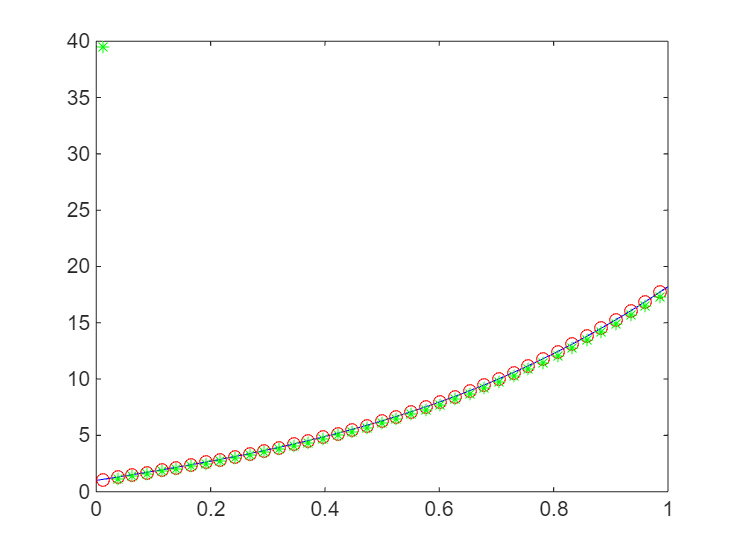

y_der = polyval(polyder(ppp),x);
xmean = (x(1:end-1) + x(2:end))/2;
plot(x,y_der,"b",xmean,D*y/h,"or",xmean(2:end),Dsym*y/h,"*g")

Теперь посмотрим на оператор второй производной:


$$\[
\frac{\partial^2 T}{\partial x^2}_{mn} \approx \frac{T^{m+1}_{n+1}  - 2T^{m+1}_{n} +T^{m+1}_{n-1}}{\Delta x^2}
\]$$



$$\[
D^2 = \frac{1}{\Delta x^2}
[\matrix{
-2 & 1 & 0 & \cdots & 0 \cr
1 & -2 & 1 & \cdots & 0 \cr
0 & 1 & -2 & \cdots & 0 \cr
\vdots & \vdots & \vdots & \ddots & 1 \cr
0 & 0 & 0 & 1 & -2
}
]$$


Уравнение (1) может быть записано в матричной форме:


$$[\frac {1}{a(T)} ]D_t \cdot [T]  =[T]\cdot D_{xx}+   [\frac{\lambda'(T)}{\lambda(T)}]([T]\cdot D_x \circ [T] \cdot D_x)$$


$\circ$ - произведение Адамара (поэлементное умножение).

Предполагаем, что теплофизические свойства определяются по температурам в предыдущий момент времени. Построим сетку для координаты и времени:


$$x_n = n\Delta x, n\in 0...N$$
 


$$t_m = m\Delta t, m\in 0...M$$
 

Задача состоит в том, чтобы выразить через производную по времени распределение температуры по толщине образца в $m+1$-й момент времени, через распределение температуры в $m$ - й момент времени. 

Подставив выражения для производных в уравнение (1) получим:


$$\frac {1}{a_{mn}\Delta t} (T^{m+1}_n - T^{m}_n)  =\frac{1}{\Delta x^2} (T^{m+1}_{n+1}  - 2T^{m+1}_{n} +T^{m+1}_{n-1})+   \frac{1}{4\Delta x^2} \frac{\lambda'_{mn}}{\lambda_{mn}} (T^{m}_{n-1} - T^{m}_{n+1})^2 $$



$$ (T^{m+1}_n - T^{m}_n)  =F_{mn}(T^{m+1}_{n+1}  - 2T^{m+1}_{n} +T^{m+1}_{n-1})+   F_{mn}\frac{\lambda'_{mn}}{4\lambda_{mn}} (T^{m}_{n-1} - T^{m}_{n+1})^2 $$



$$F_{mn}=\frac{a_{mn}\Delta t}{\Delta x^2} $$


Выразим из этого уравнения температуру для следующего момента времени:


$$ T^{m+1}_n (1 + 2F_{mn})   - F_{mn}T^{m+1}_{n+1}  + F_{mn}T^{m+1}_{n-1}  =  T^{m}_n +   F_{mn}\frac{\lambda'_{mn}}{4\lambda_{mn}} (T^{m}_{n-1} - T^{m}_{n+1})^2 $$


Пусть у нас есть вектор- столбец распределения температуры по толщине в текущий момент времени $\vec{T}^m$


$$B_m\vec{T}^{m+`1} = \vec{T}^m + K^D[H\vec{T}^m\circ H\vec{T}^m]=\vec{b}^m(\vec{T}^m)$$



$$
{B}_m = [
\matrix{
1 + 2F_{m1} & -F_{m1} & 0 & \cdots & 0 \cr
-F_{m2} & 1 + 2F_{m2} & -F_{m2} & \cdots & 0 \cr
0 & -F_{m3} & 1 + 2F_{m3} & \cdots & 0 \cr
\vdots & \vdots & \vdots & \ddots & -F_{m,N-1} \cr
0 & 0 & 0 & -F_{mN} & 1 + 2F_{mN}
}
]$$


Вектор $\vec{b}^m$ - нелинейная функция вектора распределения температуры по толщине слоя на предыдущем шаге.

Начальное условие:


$$T_n^0 = \phi(x_n)$$


Для учета граничных условий и расчета теплового потока, рекомендуется использовать разностные соотношения второго порядка точности, учитывающие накопление тепла на предыдущем шаге:

$q^{m+1}=\frac{\lambda_0^m}{\Delta x}(T_0^{m+1} - T_1^{m+1}) + C_0^m\frac{\Delta x}{2\Delta t}(T_0^{m+1} - T_0^m) $ - тепловой поток сверху

$\tilde q^{m+1}=\frac{\lambda_N^m}{\Delta x}(T_N^{m+1} - T_{N-1}^{m+1}) + C_0^m\frac{\Delta x}{2\Delta t}(T_N^{m+1} - T_N^m) $ - тепловой поток снизу

В матричной форме данные уравнения будут иметь вид

FUNTIONS

function D = Dt(M)
% M- number of input matrix rows
    D = zeros(M-1,M);
    D(diagonal_inds(0,M-1,M)) = -1;
    D(diagonal_inds(1,M-1,M)) = 1;
end
function D = Dtsym(M)
% M- number of input matrix rows
    D = zeros(M-1,M);
    D(diagonal_inds(-1,M-1,M)) = -1/2;
    D(diagonal_inds(1,M-1,M)) = 1/2;
end
function D = D2t(N)
    D = zeros(N,N);
    D(diagonal_inds(0,M-1,M)) = -2;
    D(diagonal_inds(1,M-1,M)) = 1; 
    D(diagonal_inds(-1,M-1,M)) = 1;
end
function indices = diagonal_inds(diagonal_index,rows_number, columns_number)
    % diagonalIndicesRect returns linear indices of the k-th diagonal of an m x n matrix
    % m - number of rows
    % n - number of columns
    % k - diagonal number (0 = main, >0 above main, <0 below main)
    %
    % Linear indices are returned for the elements along the specified diagonal,
    % respecting matrix dimensions.
    
    if diagonal_index >= 0
        % Diagonal above or on main
        len = min(rows_number, columns_number-diagonal_index);
        rowIdx = 1:len;
        colIdx = (1:len) + diagonal_index;
    else
        % Diagonal below main
        len = min(rows_number+diagonal_index, columns_number);
        rowIdx = (1:len) - diagonal_index;
        colIdx = 1:len;
    end
    
    % Convert row and column indices to linear indices for column-major order
    indices = sub2ind([rows_number columns_number], rowIdx, colIdx);
end